# Online Directional Convolution

clear
close all

## Grid

grid = OctoGrid(2,2,2,100);

% add column
% grid.addBox(1.25,0.9,0,0.2,0.2,1.5)
% add wall
grid.addBox(0.6,0.8,0,0.8,0.1,1.5)

## Get Convolutional Kernel

kernel_size = 31;
sigma = 1;
kernel_x = directional_kernel_3d('x', kernel_size, sigma, kernel_size, sigma, kernel_size, sigma, 'linear')

kernel_x = kernel_x(:,:,1) =

    0.0003    0.0006    0.0009    0.0012    0.0015    0.0018    0.0021    0.0024    0.0027    0.0030    0.0033    0.0036    0.0039    0.0041    0.0044         0   -0.0044   -0.0041   -0.0039   -0.0036   -0.0033   -0.0030   -0.0027   -0.0024   -0.0021   -0.0018   -0.0015   -0.0012   -0.0009   -0.0006   -0.0003
    0.0006    0.0012    0.0018    0.0024    0.0030    0.0036    0.0041    0.0047    0.0053    0.0059    0.0065    0.0071    0.0077    0.0083    0.0089         0   -0.0089   -0.0083   -0.0077   -0.0071   -0.0065   -0.0059   -0.0053   -0.0047   -0.0041   -0.0036   -0.0030   -0.0024   -0.0018   -0.0012   -0.0006
    0.0009    0.0018    0.0027    0.0036    0.0044    0.0053    0.0062    0.0071    0.0080    0.0089    0.0098    0.0107    0.0116    0.0124    0.0133         0   -0.0133   -0.0124   -0.0116   -0.0107   -0.0098   -0.0089   -0.0080   -0.0071   -0.0062   -0.0053   -0.0044   -0.0036   -0.0027   -0.0018   -0.0009
    0.0012    0.0024    0.0036    0.0

kernel_y = directional_kernel_3d('y', kernel_size, sigma, kernel_size, sigma, kernel_size, sigma, 'linear');
kernel_z = directional_kernel_3d('z', kernel_size, sigma, kernel_size, sigma, kernel_size, sigma, 'linear');

## Check field in a straight line

If we look at a streight line away from the wall (normal on wall), it should be exponentially falling.

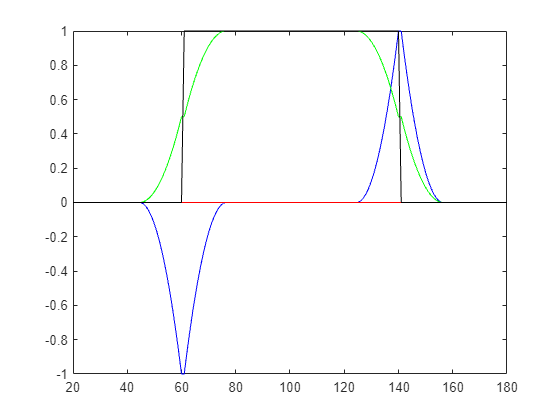

dx_list = [];
dy_list = [];
dz_list = [];

y_list = [];
ob_list = [];

y = 85;
z = 100;

for x = 20:1:180


    cutout = grid.grid(((1:kernel_size)+y-ceil(kernel_size/2)), ((1:kernel_size)+x-ceil(kernel_size/2)), ((1:kernel_size)+z-ceil(kernel_size/2)));

    C = cutout .* kernel_x; % Perform element-wise multiplication
    dx = sum(C(:)); % Sum all values  

    C = cutout .* kernel_y; % Perform element-wise multiplication
    dy = sum(C(:)); % Sum all values  

    C = cutout .* kernel_z; % Perform element-wise multiplication
    dz = sum(C(:)); % Sum all values  
    
    
    % list of dy values
    dy_list = [dy_list dy];

    % list of x coordinates
    dx_list = [dx_list dx];

    % list of z coordinates
    dz_list = [dz_list dz];

    % list of obstacle values
    ob_list = [ob_list grid.grid(y, x, z)];



    % list of y coordinates
    y_list = [y_list x];



end

figure()

plot(y_list,dx_list/max(dx_list),'b')
hold on

plot(y_list,dy_list/max(dy_list),'g')
plot(y_list,dz_list/max(dz_list),'r')

plot(y_list, ob_list,'black')